# Robotics I Mini-Project 3: Spactial Robot Arm Motion

clearvars
cd('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject3')
load('S_sphere_path.mat')
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\MATLABrelated\'))
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject3'))

## Part 1: Representations of Orientation

Conventional Cartesian positions (x,y,z) is an intuitive way to represent position and orientation; however, when dealing with robotic arms with constraints between links, end-effector might run into singularities. With other representation of rotations that accounts for the spherical path of robot arm. 

% loading s-curve data

First we discretize the path into equal segments and store them in lambda

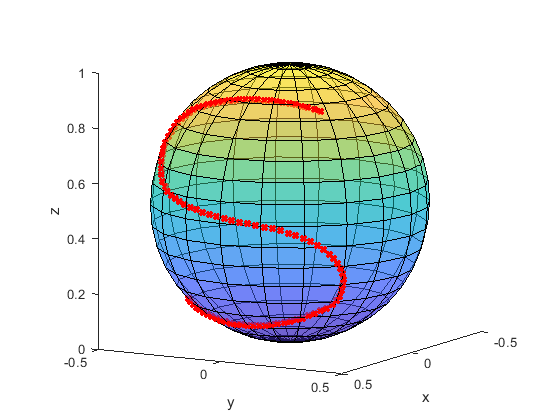

% plot the spherical S
figure(1);plot3(p_S(1,:),p_S(2,:),p_S(3,:),'rx','linewidth',3);
xlabel('x');ylabel('y');zlabel('z');
hold on;
% add a 3d sphere
surf(X,Y,Z)
% make it transparent
alpha .5
axis(r*[-1 1 -1 1 0 2]);axis('square');
view(120,10);

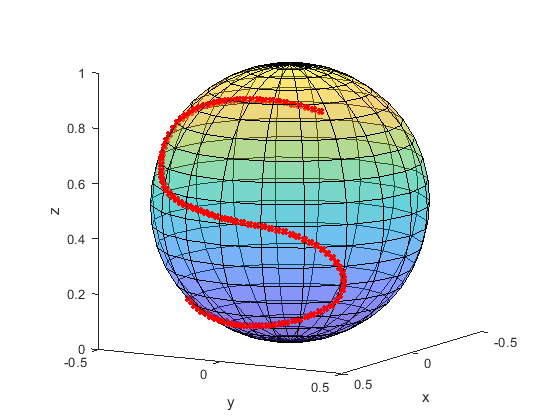

% convert to equal path length grid
diffS=vecnorm(diff(p_S')');
ls=[0 cumsum(diffS)];
lf=sum(diffS);
N=100;
l=(0:lf/N:lf);
pS=interp1(ls,p_S',l,'spline')';  % x = ls, f(x) = p_S, l = x_1, pS = f1(x_1) 
% plot it out again with equal path length
figure(2);plot3(pS(1,:),pS(2,:),pS(3,:),'rx','linewidth',3);
xlabel('x');ylabel('y');zlabel('z');
hold on;
% 3d sphere
surf(X,Y,Z)
% make it transparent
alpha 0.4
axis(r*[-1 1 -1 1 0 2]);axis('square');
view(120,10);

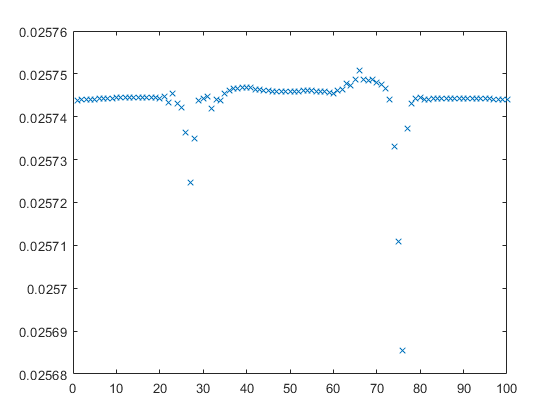

% check the path length is indeed equal
dlvec=vecnorm(diff(pS')');
figure(3);plot(dlvec,'x')

dl=mean(dlvec);
disp(max(abs(dlvec-dl)));

   5.8157e-05



Here we are allocating variables for Unit quaternions, eular angles, and angle-axis product.

%-----------------------------------
% next we find xT, yT, zT
N=length(pS);
xT=zeros(3,N);zT=zeros(3,N);yT=zeros(3,N);
quat=zeros(4,N); % allocate space for unit quaternion representation of R_{0T}
euler_rpy = zeros(3,N);
angle_axis = zeros(4,N);

We can see that the bottom of the sphere lies on (0,0,0) together with the base of the robot. For the end effector to be perpendicular to the sphere, "xT" should be the extention of a radius passing throught any points in "pS".

pc = r*[0;0;1];  % the distance from (0,0,0) to the center of the sphere.
% r is the radius of the sphere.
r = 0;p=0;q=0;
ak = 0;theta = 0;
for i=1:N
    xT(:,i)=(pS(:,i)-pc)/norm(pS(:,i)-pc);
    if i<N
        yT(:,i)=(pS(:,i+1)-pS(:,i));
    else
        yT(:,i)=yT(:,i-1);
    end
    yT(:,i)=yT(:,i)-yT(:,i)'*xT(:,i)*xT(:,i);
    yT(:,i)=yT(:,i)/norm(yT(:,i));
    zT(:,i)=cross(xT(:,i),yT(:,i));
    R=[xT(:,i) yT(:,i) zT(:,i)];
    quat(:,i)=R2q(R);
    [r,p,y] = R2rpy(R);
    euler_rpy(:,i) = [r,p,y]';
    [ak,theta] = R2kth(R);
    angle_axis(:,i) = [ak;theta];
end

Next we will look at three different representation of the path.

### (a) Unit Quaternions

In this representation, three angles are represented in four DOF. 


$$q_0 = \frac{1}{2} \sqrt{1 + r_{11}+r_{22} +r_{33}} \\ 
q_1 = \frac{1}{4q_0} (r_{32} - r_{23})\\
q_2 = \frac{1}{4q_0} (r_{13} - r_{31})\\
q_3 = \frac{1}{4q_0} (r_{21} - r_{12})\\$$


where rotation matrix:


$$R_{0T} \in \mathbb{R}^{3\times3}$$


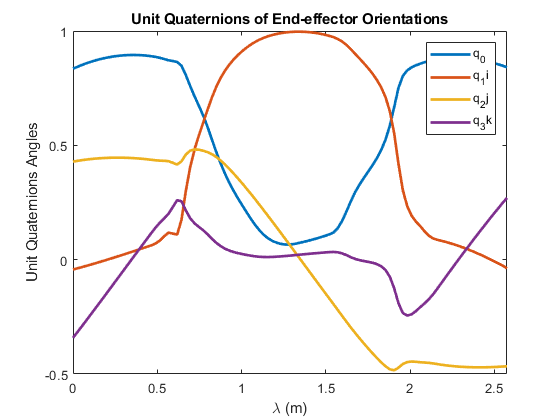

figure;
plot(l,quat,'LineWidth',2)
legend('q_0','q_1i','q_2j','q_3k')
xlim([0,l(end)])
xlabel('\lambda (m)')
ylabel('Unit Quaternions Angles')
title('Unit Quaternions of End-effector Orientations')

### (b) Euler Angles

Any cartisian rotation can be represented by 1 of the 12 Euler Angles in either fixed frame or body frame. 

In this problem we need to solve ZYX (body frame or rpy) Eular angle for each orientation of the end-effector frame. 


$$R_{0T} = R_z(\beta_1)R_y(\beta_2)Rx(\beta_3)$$


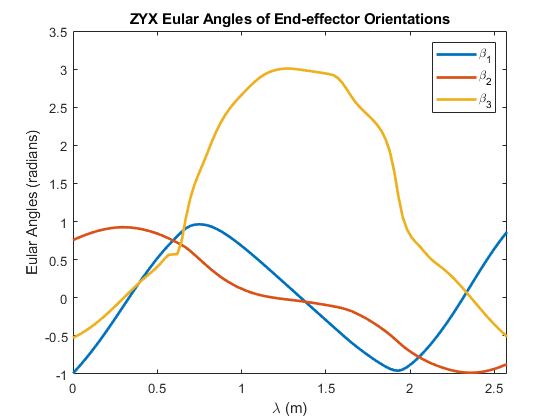

figure;
plot(l,euler_rpy,'LineWidth',2)
legend('\beta_1','\beta_2','\beta_3')
xlim([0,l(end)])
xlabel('\lambda (m)')
ylabel('Eular Angles (radians)')
title('ZYX Eular Angles of End-effector Orientations')

### (C) Angle-axis product

Another way of thinking about rotation is that any combinations of SO(3) rotation can be represented as rotation of certain degree about one axis:


$$R_{0T} = e^{\beta^\times}, \text{ where }\beta = k\theta$$


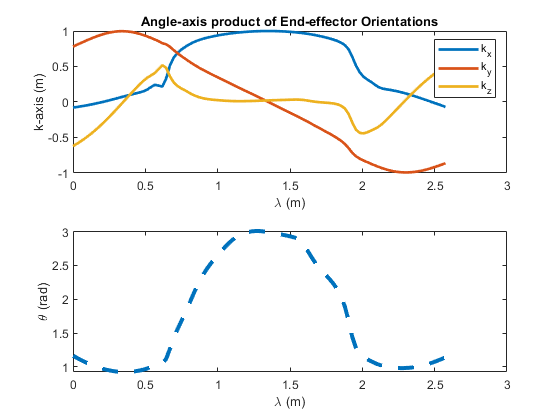

figure;
subplot(2,1,1)
plot(l,angle_axis(1:3,:),'LineWidth',2) 
legend('k_x','k_y','k_z')
xlabel('\lambda (m)')
ylabel('k-axis (m)')
title('Angle-axis product of End-effector Orientations')
subplot(2,1,2)
plot(l,angle_axis(4,:),'LineWidth',3,'LineStyle',"--")
xlabel('\lambda (m)')
ylabel('\theta (rad)')

## Part 2: ABB IRB 1200-5/0.9 robot

The purpose of this part is to understand the motion control of IRB 1200 and to derive relativd equations to model its end-effector motion.

### (a) 

Given physical parameters of IRB 1200, we want to be able to represent it in POE, SDH, and MDH. 

syms L1 L2 L3 L4 L5 real
syms q1 q2 q3 q4 q5 q6 real

1. First in Product of Exponential 

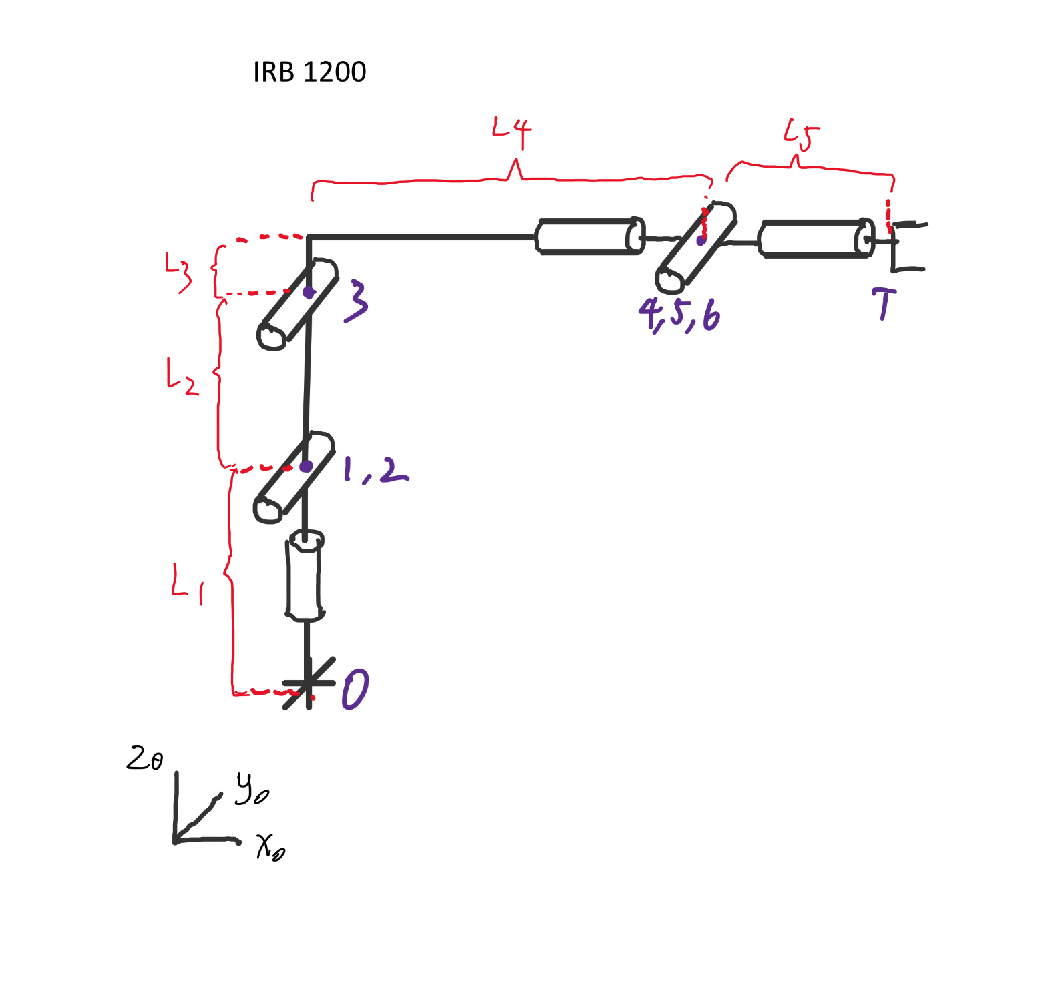

figure;
imshow('IRB1200drawing.png')

% P: ositon vector of each link
zz=zeros(3,1); ex = [1;0;0]; ey = [0;1;0]; ez = [0;0;1];
p01=0*ex+L1*ez;
p12=zz;
p23=L2*ez;
p34=L3*ez+L4*ex;
p45=zz;
p56=zz;
p6T=L5*ex;
% H: rotation axis
h1=ez;
h2=ey;
h3=ey;
h4=ex;
h5=ey;
h6=ex;
% Show in table
POE_i = {'1';'2';'3';'4';'5';'6';'T'};
POE_p = {'L1*ez';'0';'L2*ez';'L3*ez+L4*ex';'0';'0';'L5*ex'};
POE_h = {'ez';'ey';'ey';'ex';'ey';'ex';'ex'};
POE_config = table(POE_i,POE_h,POE_p)

POE_config = 7×3 table
    POE_i    POE_h          POE_p     
    _____    ______    _______________

    {'1'}    {'ez'}    {'L1*ez'      }
    {'2'}    {'ey'}    {'0'          }
    {'3'}    {'ey'}    {'L2*ez'      }
    {'4'}    {'ex'}    {'L3*ez+L4*ex'}
    {'5'}    {'ey'}    {'0'          }
    {'6'}    {'ex'}    {'0'          }
    {'T'}    {'ex'}    {'L5*ex'      }


2. Representing IRB1200 in Standard Denavit-Hartenberg frame

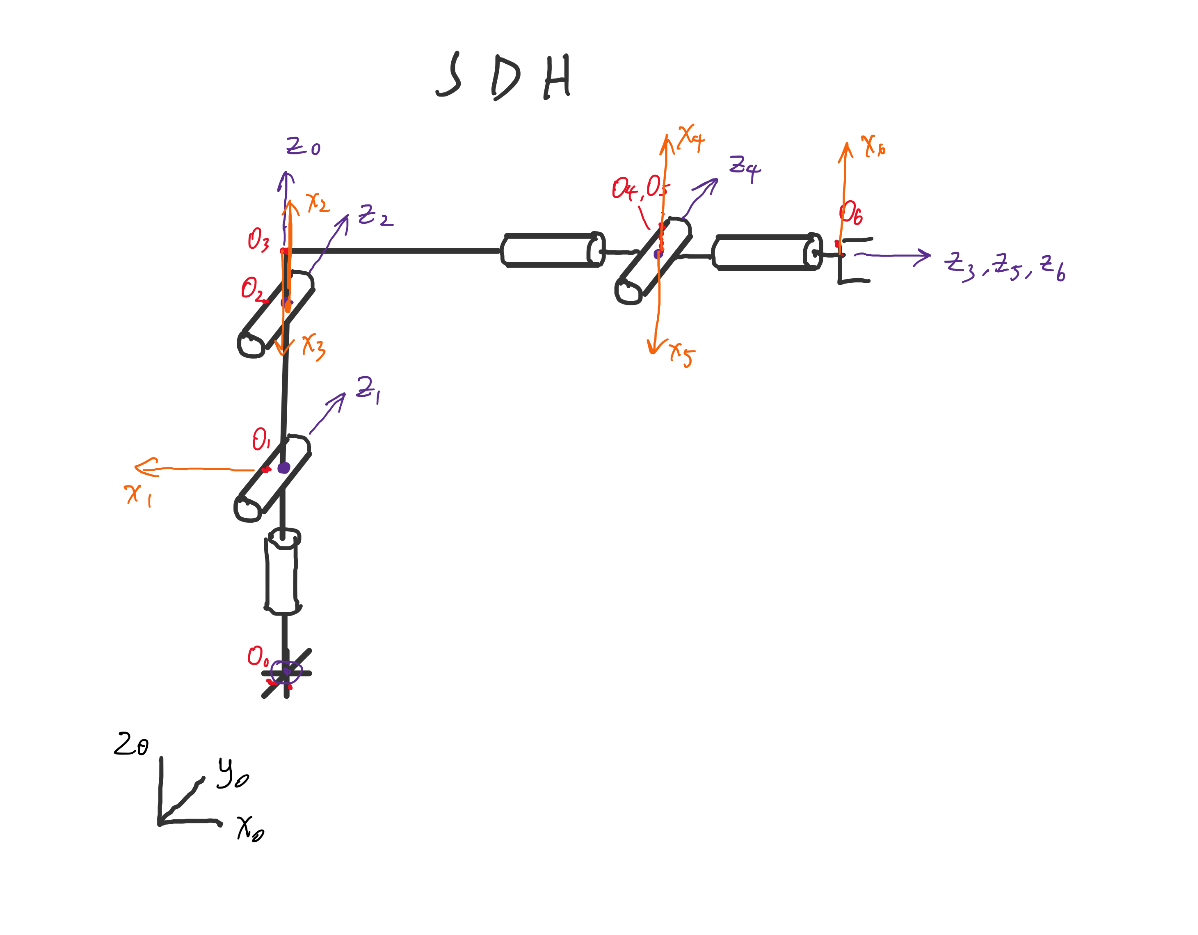

imshow("SDH.png")

% Show in table
SDH_i = {'1';'2';'3';'4';'5';'6'};
SDH_d = string([L1,0,0,L4,0,L5]');
SDH_a = string([0,L2,-L3,0,0,0]');
SDH_alpha = string(sym([pi/2,0,pi/2,pi/2,pi/2,0]'));
SDH_theta = string((sym([pi,pi/2,pi,pi,pi,pi])+[q1,q2,q3,q4,q5,q6])');
SDH_config = table(SDH_i,SDH_d,SDH_a,SDH_alpha,SDH_theta)

SDH_config = 6×5 table
    SDH_i    SDH_d    SDH_a    SDH_alpha     SDH_theta 
    _____    _____    _____    _________    ___________

    {'1'}    "L1"     "0"       "pi/2"      "q1 + pi"  
    {'2'}    "0"      "L2"      "0"         "q2 + pi/2"
    {'3'}    "0"      "-L3"     "pi/2"      "q3 + pi"  
    {'4'}    "L4"     "0"       "pi/2"      "q4 + pi"  
    {'5'}    "0"      "0"       "pi/2"      "q5 + pi"  
    {'6'}    "L5"     "0"       "0"         "q6 + pi"  


3. Representing IRB1200 in Modified Denavit-Hartenberg frame

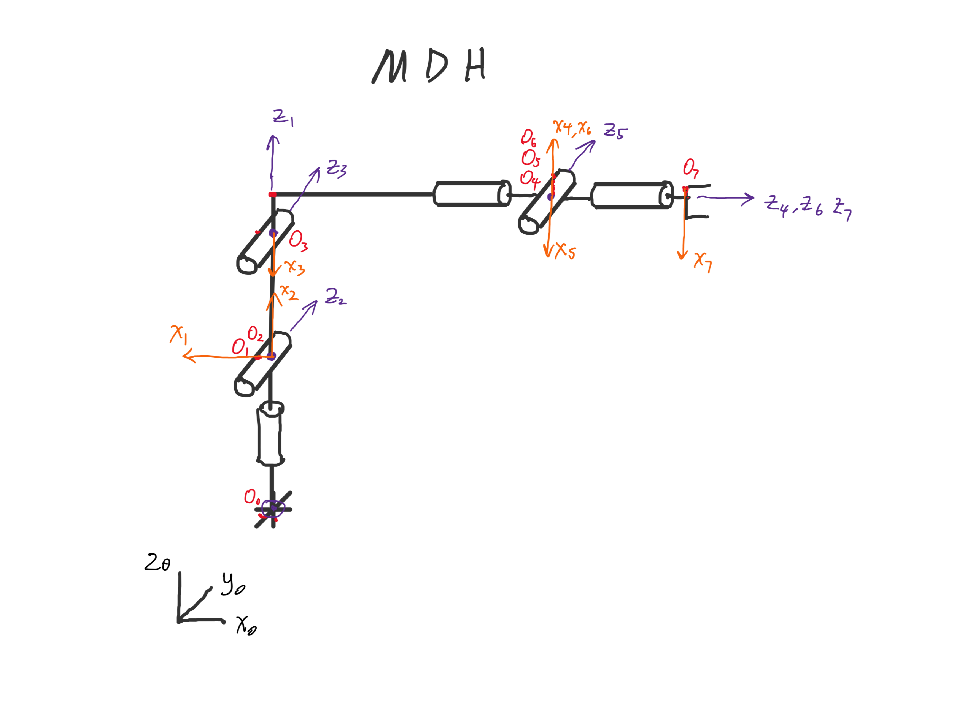

imshow("MDH.png")

% Show in table
MDH_i = {'1';'2';'3';'4';'5';'6';'7'};
MDH_d = string([L1,0,0,L4,0,0,L5]');
MDH_ai_1 = string([0,0,L2,-L3,0,0,0]');
MDH_alpha = string(sym([0,pi/2,0,pi/2,pi/2,pi/2,0]'));
MDH_theta = string((sym([pi,pi/2,pi,pi,pi,pi,pi])+[q1,q2,q3,q4,q5,q6,0])');
MDH_config = table(MDH_i,MDH_d,MDH_ai_1,MDH_alpha,MDH_theta)

MDH_config = 7×5 table
    MDH_i    MDH_d    MDH_ai_1    MDH_alpha     MDH_theta 
    _____    _____    ________    _________    ___________

    {'1'}    "L1"      "0"         "0"         "q1 + pi"  
    {'2'}    "0"       "0"         "pi/2"      "q2 + pi/2"
    {'3'}    "0"       "L2"        "0"         "q3 + pi"  
    {'4'}    "L4"      "-L3"       "pi/2"      "q4 + pi"  
    {'5'}    "0"       "0"         "pi/2"      "q5 + pi"  
    {'6'}    "0"       "0"         "pi/2"      "q6 + pi"  
    {'7'}    "L5"      "0"         "0"         "pi"       


### (b) 

With POE, SDH, and MDH defined, calculate and compare the forward kinematics of all three representations. We do that by first define a sets of angles and then measure the difference of the end-effector frames between all three methods. 

q = [0,0,0,0,0,pi/2]; %  end-effector pointing up ward

1. In POE convention, calculate the forward kinematics

% IRB 1200 robot using POE convention
irb1200_poe.q = q;
irb1200_poe.P=[p01 p12 p23 p34 p45 p56 p6T]; % unit in meter
irb1200_poe.H=[h1 h2 h3 h4 h5 h6];
irb1200_poe.joint_type=[0 0 0 0 0 0]; % all rotational joint
irb1200_poe = nlinkfwdkin(irb1200_poe);
disp('T_{0T} from POE')

T_{0T} from POE


disp(irb1200_poe.T)

$$\left(\begin{array}{cccc} 1 & 0 & 0 & L_{4}+L_{5}\\ 0 & \frac{1}{9007199254740992} & -1 & 0\\ 0 & 1 & \frac{1}{9007199254740992} & L_{1}+L_{2}+L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

2. In SDH convention, calculate the forward kinematics

irb1200_sdh.d = [L1,0,0,L4,0,L5];
irb1200_sdh.a = [0,L2,-L3,0,0,0];
irb1200_sdh.alpha = sym([pi/2,0,pi/2,pi/2,pi/2,0]);
irb1200_sdh.theta = sym([pi,pi/2,pi,pi,pi,pi])+q;
% Match then end-effector frame to POE
T6T=[[[0 0 1 ; 0 -1 0; 1 0 0] zeros(3,1)];[zeros(1,3) 1]];
irb1200_sdh = fwdkinsdh(irb1200_sdh);
T0T_sdh = simplify(irb1200_sdh.T*T6T)

$$T0T\_sdh = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{4}+L_{5}\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & L_{1}+L_{2}+L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

disp('difference between POE and SDH')

difference between POE and SDH


disp(double(irb1200_poe.T-T0T_sdh));

   1.0e-15 *

         0         0         0         0
         0    0.1110         0         0
         0         0    0.1110         0
         0         0         0         0



With very small discrepancy ($10^{-15}$), we assured that POE and SDH has the same transformation.

3. In MDH convention, calculate the forward kinematics

irb1200_mdh.d = [L1,0,0,L4,0,0,L5];
irb1200_mdh.a = [0,0,L2,-L3,0,0,0];
irb1200_mdh.alpha = sym([0,pi/2,0,pi/2,pi/2,pi/2,0]);
irb1200_mdh.theta = sym([pi,pi/2,pi,pi,pi,pi,pi])+[q,0];
% Match then end-effector frame to POE
T7T=[[[0 0 -1 ; 0 1 0; 1 0 0] zeros(3,1)];[zeros(1,3) 1]];
irb1200_mdh = fwdkinmdh(irb1200_mdh);
T0T_mdh = simplify(irb1200_mdh.T*T7T)

$$T0T\_mdh = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{4}+L_{5}\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & L_{1}+L_{2}+L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

disp('difference between POE and MDH')

difference between POE and MDH


disp(double(irb1200_poe.T-T0T_mdh));

   1.0e-15 *

         0         0         0         0
         0    0.1110         0         0
         0         0    0.1110         0
         0         0         0         0



With very small discrepancy ($10^{-15}$), we assured that POE and MDH has the same transformation.

Therefore, POE, SDH, and MDH are the same transformation.

### (c) 

Using subproblems, calculate inverse kinematics for IRB1200 using POE

1. we include numerical parameters for IRB1200

% ABB IRB 1200 parameters
L1=399.1;
L2=448;
L3=42;
L4=451;
L5=82;
% P: positon vector of each link
p01=0*ex+L1*ez;
p12=zz;
p23=L2*ez;
p34=L3*ez+L4*ex;
p45=zz;
p56=zz;
p6T=L5*ex;
% H: rotation axis
h1=ez;
h2=ey;
h3=ey;
h4=ex;
h5=ey;
h6=ex;
% IRB 1200 robot using POE convention
irb1200.P=[p01 p12 p23 p34 p45 p56 p6T]/1000; % unit in meter
irb1200.H=[h1 h2 h3 h4 h5 h6];
irb1200.joint_type=[0 0 0 0 0 0]; % all rotational joint

2. we then perform forward kinematics with a known set of joint angles.

% Create the Robot object
radius=.01;
[irb1200_rbt,colLink]=defineRobot(irb1200,radius);
irb1200.q = [0.1,0.2,-0.3,0.4,0.3,-0.2];  % known angles
disp('Preset angles');

Preset angles


disp(irb1200.q)

    0.1000    0.2000   -0.3000    0.4000    0.3000   -0.2000



irb1200 = nlinkfwdkin(irb1200);
disp('T_{0T} from POE method')

T_{0T} from POE method


disp(irb1200.T);

    0.9614   -0.1762    0.2115    0.6097
    0.2121    0.9638   -0.1613    0.0707
   -0.1755    0.1999    0.9640    0.9106
         0         0         0    1.0000



robot = irb1200;

3. preparing variables for inverse kinematics calculation

p0T = robot.T(1:3,4);
r0T = robot.T(1:3,1:3);
links = robot.P; %  3xn joint length in its own frame
% postion vectors of the arm
p01 = links(:,1); p12 = links(:,2); p23 = links(:,3); p34 = links(:,4);
p45 = links(:,5); p56 = links(:,6); p6T = links(:,7);


$$p_{0T} = p_{01} + R_{01}p_{12}  +R_{02}p_{23}+R_{03}p_{34}+R_{04}p_{45}+R_{05}p_{56}+R_{06}p_{6T}$$



$$p_{0T} - p_{01} -R_{06}p_{6T} = R_{02}p_{23}+R_{03}p_{34}$$


known on the left, unknown on the right, we can rewrite this equation to the follwoing:


$$||(p_{16})_0|| = ||R_{02}(p_{23} + R_{23}p_{34})||$$



$$||p_{16}|| = ||p_{23} - (-e^{h3 \times q3}p_{34})||$$


we can solve for $q3$ in $R_{23}$ using subproblem3:

% a sphere with r = norm(p16)
% a p23 offseted cone of p34 waist height
% intersecting the sphere
% max two sol (maybe infinity?)
p16 = p0T - p01 - r0T*p6T;
q3 = subprob3(robot.H(:,3),-p34,p23,norm(p16));

as q3(2) = -0.3 matches with the previously generated angle, procede to solve for $q1 \text{ and } q2 $ using subproblem2 with equation:


$$e^{-h1^\times q1}(p_{16})_0 = e^{h2^ \times q2}(p_{23} + e^{h3 ^\times q3} p_{34})$$


% two cone with equal waist height intersecting 
% max two sol 
q1 = zeros(length(q3)*2,1);
q2 = zeros(length(q3)*2,1);
q3_holder = q2;  % to expand q3 to 4 by 1
for i = 1:length(q3)
    p24 = p23 + expm(hat(robot.H(:,3))*q3(i))*p34;
    [q1(2*i-1:2*i,:),q2(2*i-1:2*i,:)] = subprob2(-robot.H(:,1),robot.H(:,2),p16,p24);
    q3_holder(2*i-1:2*i,:) = ones(2,1)*q3(i);
end
q3 = q3_holder;

For the rest angles: $q4, q5,q6$, we can solve them from the following equations:


$$R_{0T} = R_{01}R_{12}R_{23}R_{34}R_{45}R_{56}R_{6T}$$



$$R_{32}R_{21}R_{10}R_{0T} = R_{34}R_{45}R_{56}$$


rewrite in matrix exponential form to:


$$e^{-h4^\times q4}\left(e^{-h3^\times q3 - h2^\times q2 - h1^\times q1} R_{0T} \cdot h6\right) = e^{h5^\times q5}\cdot h6$$


solve for $q4$ and $q5$ using subproblem2:

% next, obtain q4 q5 with subproblem2
q4 = zeros(length(q3)*2,1);
q5 = q4;
q123_holder = zeros(length(q3)*2,3);
for i = 1:length(q3)
    r3T = expm(-hat(robot.H(:,3))*q3(i))*expm(-hat(robot.H(:,2))*q2(i))...
        *expm(-hat(robot.H(:,1))*q1(i))*r0T;
    [q4(2*i-1:2*i,:),q5(2*i-1:2*i,:)] = subprob2(-robot.H(:,4),robot.H(:,5),...
        r3T*robot.H(:,6),robot.H(:,6));
    q123_holder(2*i-1:2*i,:) = ones(2,3).*[q1(i),q2(i),q3(i)];
end
q1 = q123_holder(:,1); q2 = q123_holder(:,2); q3 = q123_holder(:,3);

% lastly obtain q6 with subproblem1
q6 = zeros(length(q3),1);
for i = 1:length(q3)
    r5T = expm(-hat(robot.H(:,5))*q5(i))*expm(-hat(robot.H(:,4))*q4(i))...
        *expm(-hat(robot.H(:,3))*q3(i))*expm(-hat(robot.H(:,2))*q2(i))...
        *expm(-hat(robot.H(:,1))*q1(i))*r0T;
    q6(i) = subprob1(robot.H(:,6),robot.H(:,3),r5T*robot.H(:,3));
end
qout = wrapToPi([q1,q2,q3,q4,q5,q6])

qout =     0.1000    1.3853   -2.6559    0.1162    1.4490    0.1697
    0.1000    1.3853   -2.6559   -3.0254   -1.4490   -2.9719
   -3.0416   -0.2000   -2.6559   -2.8879    0.4764   -0.0426
   -3.0416   -0.2000   -2.6559    0.2537   -0.4764    3.0990
    0.1000    0.2000   -0.3000    0.4000    0.3000   -0.2000
    0.1000    0.2000   -0.3000   -2.7416   -0.3000    2.9416
   -3.0416   -1.3853   -0.3000   -3.0260    1.6335    0.1911
   -3.0416   -1.3853   -0.3000    0.1156   -1.6335   -2.9505


robot.q

ans =     0.1000    0.2000   -0.3000    0.4000    0.3000   -0.2000


Clearly, row 5 was the input angles before forward kinematics.

## Part 3: S-shaped Path Tracking with IRB1200

Now that we have inverse kinematics to configure all six angles of the robot at specific end-effector postions, we can have IRB1200 to trace out the s-shaped path. At the same time, we can study which pose out of all eight poses gives us the fastest path speed. 

1. With end-effector orientation [xT,yT,zT] and postion pS calcuated from Part 1, we can track the S-shape using file inkinABB.m

   3.7049e-16

   2.6442e-16

   3.3870e-16

   2.5821e-16

   2.6702e-16

   3.5370e-16

   5.2458e-16

   3.2182e-16

   3.9005e-16

   2.2935e-16

   2.3865e-16

   3.9636e-16

   5.4529e-16

   3.1979e-16

   2.4478e-16

   4.6680e-16

   3.0537e-16

   3.0091e-16

   6.0027e-16

   3.2129e-16



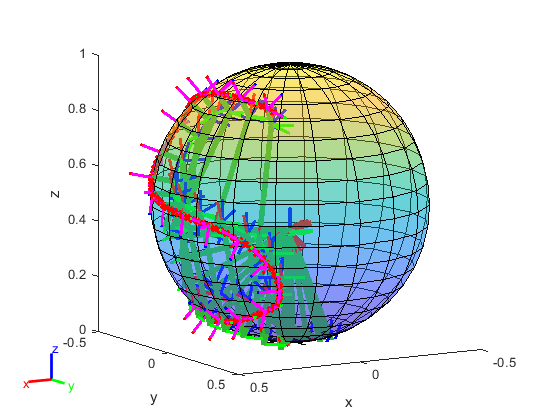

solnNumber = 1;
q = zeros(6,N);
for i=1:N
    % specify end effector SE(3) frame
    %Td{i}=[[xT(:,i) yT(:,i) zT(:,i)]*R6T' pS(:,i);[0 0 0 1]];
    Td{i}=[[xT(:,i) yT(:,i) zT(:,i)] pS(:,i);[0 0 0 1]];
    irb1200.T=Td{i};
    %
    qsolns=invkinABB(irb1200); % output eight solutions
    q(:,i) = qsolns(solnNumber,:)';  % first solution (q = 1 x 6)
    % check forward kinematics to make sure the IK solution is correct
    irb1200.q=q(:,i)';
    irb1200=nlinkfwdkin(irb1200);
    T{i}=irb1200.T;
    % show robot pose (ever 10 frames)
    if mod(i,5)==0
        disp(norm(T{i}-Td{i}));
        figure(2);show(irb1200_rbt,q(:,i),'collision','on');        
        view(150,10);
    end
end

2. Now if we pose an angular velocity constraints $\frac{dq}{dt} = 2 $rad/sec, we would like to know which pose out of all eight poses has the fastest constant path velocity $\frac{d\lambda}{dt}$:


$$\frac{dq}{dt} = \frac{dq}{d\lambda} \cdot \frac{d\lambda}{dt}$$


as $\frac{d\lambda}{dt}$ need to satisfy all angles at this instance, the maximum $\frac{dq}{d\lambda} 
$ would give us a safe $\frac{d\lambda}{dt}$ .

ldot = zeros(8,100);
q3s = zeros(8,101);
dq3 = zeros(8,1);
for sol = 1:8
    for i = 1:N
        Td{i}=[[xT(:,i) yT(:,i) zT(:,i)] pS(:,i);[0 0 0 1]];
        irb1200.T=Td{i};
        qsolns=invkinABB(irb1200); % output eight solutions
        q(:,i) = qsolns(sol,:)';
    end
    dqdl = max(abs(diff(q')'))./diff(l')';
    ldot(sol,:) = 2./dqdl;
    %  elbow joint q3 variation
    q3s(sol,:) = q(3,:);
    dq3(sol) = max(q(3,:)') - min(q(3,:)');
end
[pose_min,pose_min_index] = min(ldot,[],2);
[ldot_max,pose] = max(pose_min)

ldot_max = 0.1518

pose = 6

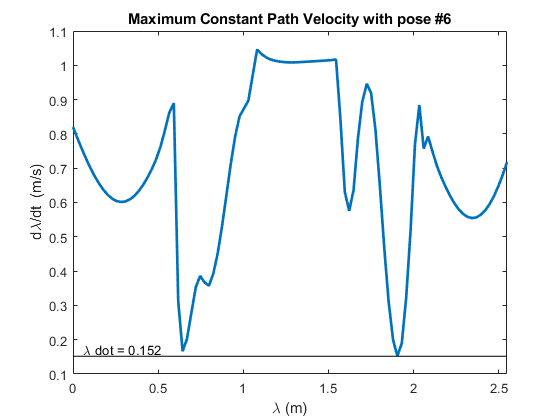

figure;plot(l(1:end-1),ldot(pose,:),'linewidth',2);
hold on;
hline(ldot_max,'k',['\lambda dot = ',num2str(round(ldot_max,3))]);
hold off
xlabel('\lambda (m)')
ylabel('d\lambda/dt  (m/s)')
xlim([0,l(end-1)])
title('Maximum Constant Path Velocity with pose #6')

while there are 8 ways for IRB1200 to track the path, most other pose has intense discontinuities across the path. pose 6, however, has overall smooth path. It's speed was constrained by near singlerity position near the turning point of the "S" shape.

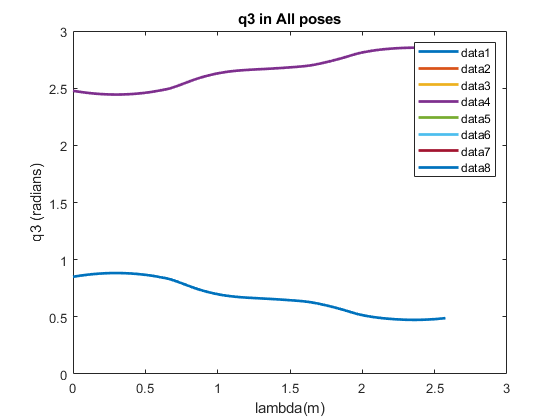

figure;plot(l,q3s,'LineWidth',2);
xlabel('lambda(m)')
ylabel('q3 (radians)')
title('q3 in All poses')
legend

dq3

dq3 =     0.4096
    0.4096
    0.4096
    0.4096
    0.4096
    0.4096
    0.4096
    0.4096


It is quite counterintuitive that the variation of q3 are the same for all poses; however, thinking more indepthly, there're only two choices from the result of subproblem3. 

## Part 4: End-effector Spatial Velocity

Knowing pose #6 to be the fastest pose with $\frac{d \lambda}{dt} = 0.152 m/s$, the end-effector angular velocity can be calculated using the follwoing equation:


$$\dot{R}_{0T}(k) = \frac{R_{0T}(k+1)-R_{0T}(k)}{\lambda_{k+1}-\lambda_k} \cdot \frac{d \lambda}{dt}$$



$$\left(\omega_T(k)\right)_0=\left(\dot{R_{0T}}(k)R_{0T}^T(k)\right)^V$$



$$(\dot{P_T}(k))_0 = \frac{p_{0T}(k+1)-p_{0T}(k)}{\lambda(k+1)-\lambda(k)} \cdot \frac{d\lambda}{dt} \text{, where } k \in \{1,2,\cdots, N-1\}$$


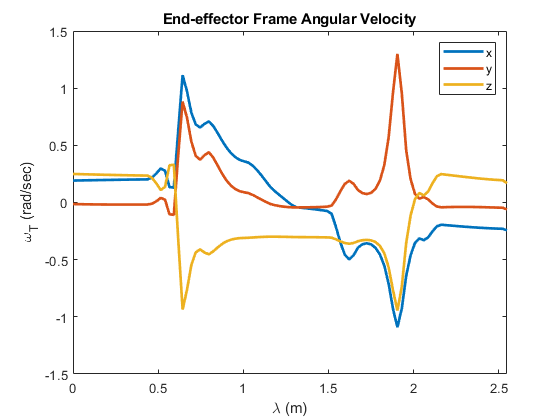

wT = zeros(3,N-1);
pTdot = zeros(3,N-1);
for k = 1:N-1
    dT0T = Td{k+1} - Td{k};
    % calculating omegaT
    dr0T = dT0T(1:3,1:3);
    rdot = dr0T/(l(k+1)-l(k))*ldot_max;
    r0T = Td{k}(1:3,1:3);
    wT(:,k) = vee(rdot*r0T');
    % calculating pTdot
    dp0T = dT0T(1:3,4);
    p0T = Td{k}(1:3,4);
    pTdot(:,k) = dp0T/(l(k+1)-l(k))*ldot_max;
end

figure;
plot(l(1:N-1),wT,'linewidth',2);
xlabel('\lambda (m)')
ylabel('\omega_{T} (rad/sec)')
legend('x','y','z')
xlim([0,l(N-1)])
title('End-effector Frame Angular Velocity')

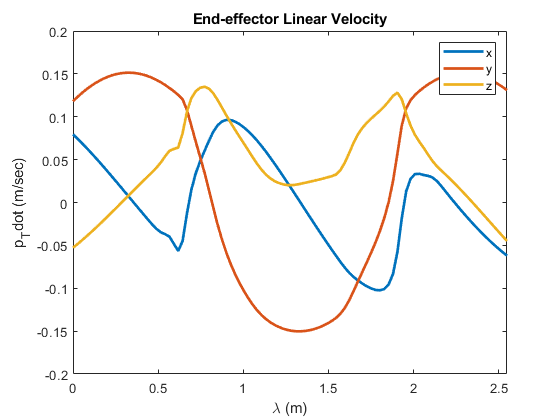


figure;
plot(l(1:N-1),pTdot,'linewidth',2);
xlabel('\lambda (m)')
ylabel('p_Tdot (m/sec)')
legend('x','y','z')
xlim([0,l(N-1)])
title('End-effector Linear Velocity')

By visually inspecting the result, both plots are quite reasonable. The kink at $\lambda = 0.64
$ was also shown at the $\dot\lambda$ plot from Part3 4). As arm pos gets closer to singularity, the rotation speed of joints increase and cause the two spikes in the first plot.